### Produce a scree plot of the standardized Iris dataset,

### using all 4 columns. What can you conclude from the

### scree plot?

iris = load('fisheriris.mat');
data = iris.meas;
yvec = iris.species;
data_std = zscore(data);
[u, s, v] = svd(data_std);
r = rank(data_std);
plot(sum(s)/sum(sum(s)));

### Using the 3rd and 4th columns of the Iris dataset, perform

### k-means clustering using the following line of code. Write

### MATLAB code to calculate the percentage of correctly

### clustered points

iris = load('fisheriris.mat');
data = iris.meas;
yvec = iris.species;

species = categorical(yvec);
species = renamecats(species,{'setosa','versicolor','virginica'},{'1','2','3'});
species = str2double(string(species));

x = data(:, 3:4);
clusters = kmeans(x, 3, 'start', [1.5 0.3; 4.2 1.3; 5.9 2.1]);

correct = sum((clusters == species) == 1);
disp(correct / size(clusters, 1))





### Using the 3rd and 4th columns of the Iris dataset, perform

### 2 iterations of the k-means clustering algorithm using the

### following centroids:

### [1, 0.5]

### [4.1 1.8]

iris = load('fisheriris.mat');
data = iris.meas;
yvec = iris.species;

centroids = [1,0.5;4.1,1.8];
x = data(:,3:4);
[idx, centroidF, sumd] = kmeans(x, 2, 'Start', centroids);
centroidF
[idx, centroidF, sumd] = kmeans(x, 2, 'Start', centroidF);
centroidF






### Using the 3rd and 4th columns of the Iris dataset, perform

### PCA of standardized data to reduce the data to 1D.

### Which, if any, of the 3 labels are linearly separable?

iris = load('fisheriris.mat');
data = iris.meas;
species = iris.species;

Xmat = data(:,3:4);
XmatS = zscore(Xmat);

[U,S,V] = svd(XmatS);

Z1 = XmatS*V(:,1);
[n, ~] = size(Xmat);
yvec = zeros(n,1);
gscatter(Z1,yvec,species);

speciesNum = grp2idx(species);
gscatter(Z1, speciesNum, species);


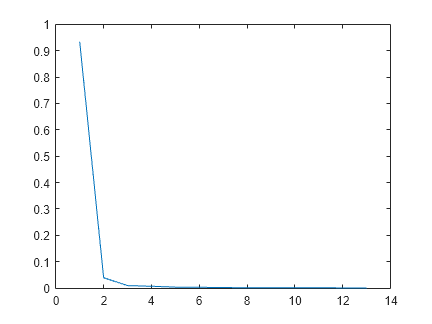

A = csvread("wine.csv",0,1);
A = A'; %Cultivar is now top row
lvec = A(:,1);
Xmat = A(:,2:end);
XmatZM = Xmat - mean(Xmat);

[u, s, v] = svd(XmatZM);
plot(diag(s)/sum(sum(s)));

singular_values = diag(s);
explained_variance = singular_values.^2 / sum(singular_values.^2);
ev = sum(diag(singular_values)).^2

ev = 1.0e+07 *

    1.7559    0.0031    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


cumulative_variance = cumsum(explained_variance);

cumulative_variance(2)

ans = 0.9998